## Task 1

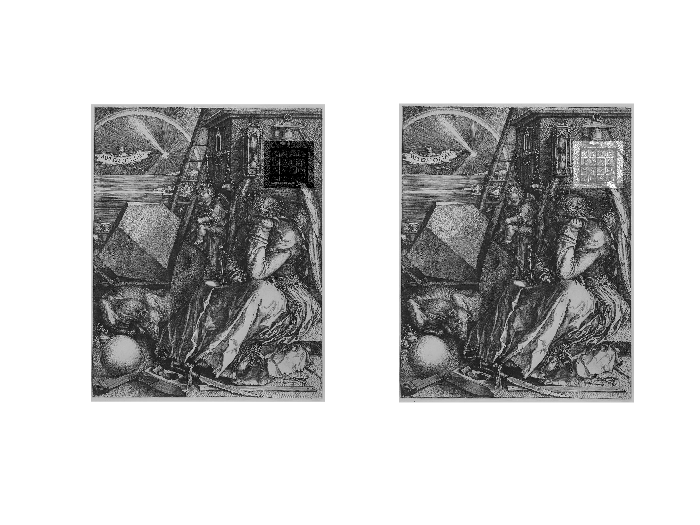

f = imread('Melencolia.jpg') ;

hidden_image_b = f;
hidden_image_w = f;
i = 75;

hidden_image_b(150:340 , 700:900) = f(150:340 , 700:900) - i ;
hidden_image_w(150:340 , 700:900) = f(150:340 , 700:900) + i ;

extract_image = hidden_image_w(150:340 , 700:900) ;

figure(1)
subplot(1,2,1)
imshow(hidden_image_b)
subplot(1,2,2)
imshow(hidden_image_w)

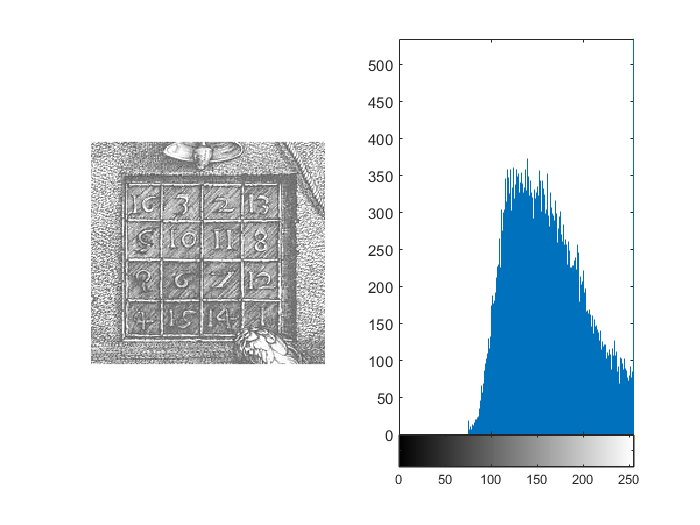


figure(2)
i = extract_image ; % Enhanced Intensity of extracted image
subplot(1,2,1)
imshow(i)
subplot(1,2,2)
imhist(i)

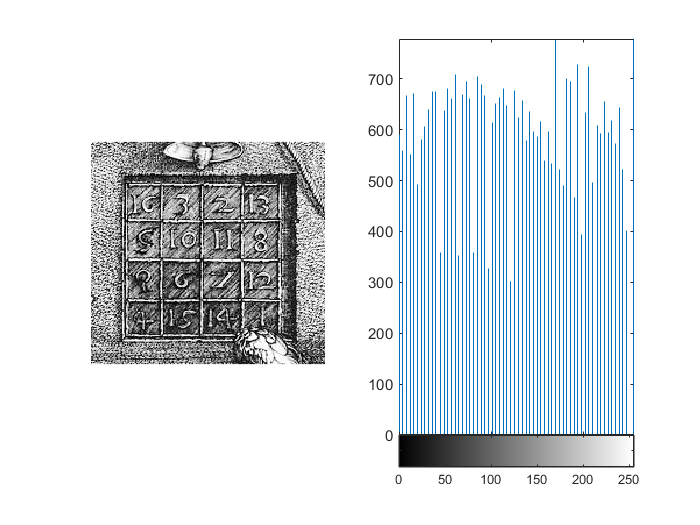


figure(3)
j = histeq(i) ; % Enhanced Contrast of extracted image
subplot(1,2,1)
imshow(j)
subplot(1,2,2)
imhist(j)


A = [16 3 2 13 ; 
     5 10 11 8 ; 
     9 6 7 12  ;
     4 15 14 1 ]

A =     16     3     2    13
     5    10    11     8
     9     6     7    12
     4    15    14     1


% Sum of Each Row
sum_row_1 = sum(A(1,:))

sum_row_1 = 34

sum_row_2 = sum(A(2,:))

sum_row_2 = 34

sum_row_3 = sum(A(3,:))

sum_row_3 = 34

sum_row_4 = sum(A(4,:))

sum_row_4 = 34


% Sum of Each Column
sum_col_1 = sum(A(:,1))

sum_col_1 = 34

sum_col_2 = sum(A(:,2))

sum_col_2 = 34

sum_col_3 = sum(A(:,3))

sum_col_3 = 34

sum_col_4 = sum(A(:,4))

sum_col_4 = 34


% Sum of Diagonal
sum_diag_1 = trace(A)

sum_diag_1 = 34

sum_diag_2 = sum(diag(flip(A)))

sum_diag_2 = 34

## Task 2

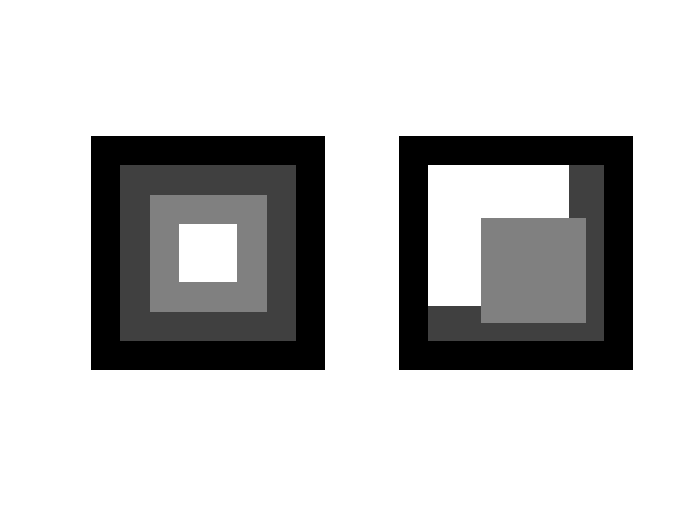

figure(4)
% Original Pattern
A=zeros(200,200,'uint8'); %200 x 200 matrix of all zeros
B=64*ones(150,150,'uint8');%150 x 150 matrix, all elements 64
C=128*ones(100,100,'uint8'); %100 x 100 matrix, all 128
D=255*ones(50,50,'uint8') ; %50 x 50 matrix, all 255
A(26:175,26:175)=B;
A(51:150,51:150)=C;
A(76:125,76:125)=D;
subplot(1,2,1)
imshow(A); 
% New Pattern
A1 = zeros(200,200,'uint8') ; 
B1 = 64 * ones(150,150,'uint8') ;
C1 = 255 * ones(120,120,'uint8') ;
D1 = 128 * ones(90,90,'uint8') ;

A1(26:175 , 26:175) = B1 ;
A1(26:145 , 26:145) = C1 ;
A1(71:160 , 71:160) = D1 ;
subplot(1,2,2)
imshow(A1)

## Task 3

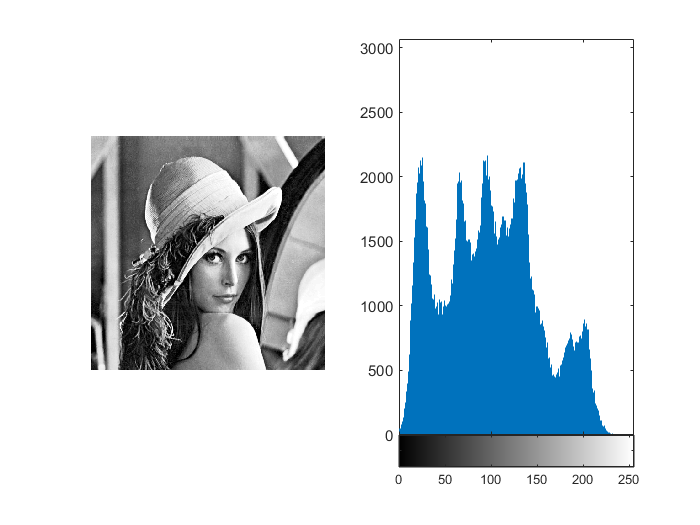

figure(5)
l = imread('lena.jpg') ;
% Oringinal Photo with Histogram
subplot(1,2,1)
imshow(l)
subplot(1,2,2)
imhist(l)
% Contrast Enhanced Image with Histogram
l_e = histeq(l) ;
subplot(1,2,1)
imshow(l_e)

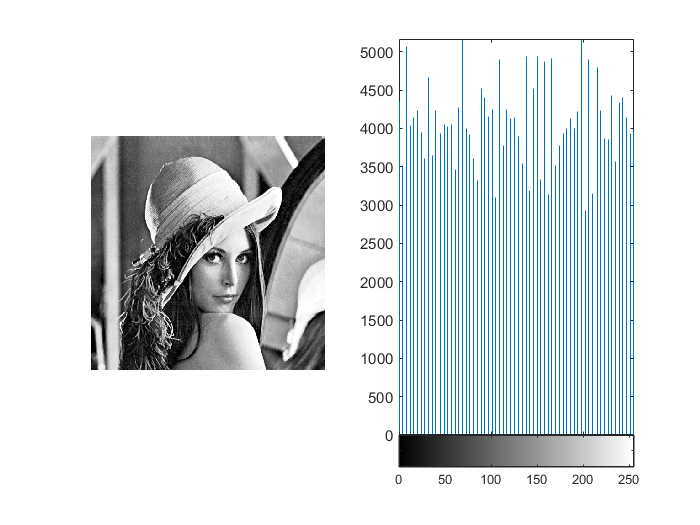

subplot(1,2,2)
imhist(l_e)

## Task 4

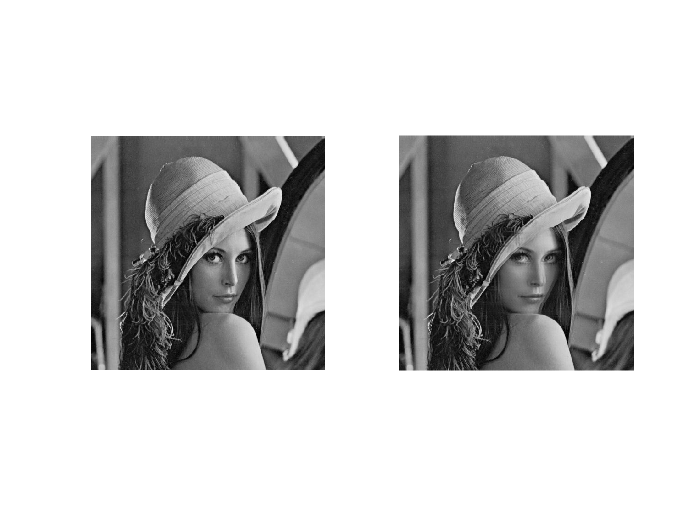

figure(6)
blurred_l = l ;
blurred_l(200:390 , 200:350) =0.5*blurred_l(200:390 , 200:350) + 0.5*blurred_l(200:390 , 207:357) ;

subplot(1,2,1)
imshow(l)
subplot(1,2,2)
imshow(blurred_l)